# Estimation of Randomly Occurring Deterministic Disturbances

## Guide to using the MATLAB code in this directory

Author:    Bill Tubbs

Date:    August 2021

Main files used in this tutorial:

- `kalman_filter.m`

- `kalman_update.m`

- `mkf_filter.m`

- `mkf_filter_AFMM.m`

- `mkf_filter_RODD.m`

- `sample_random_shocks.m`

- `sys_rodin_step.m`

- `update_AFMM.m`

- `update_KF.m`

Other dependencies required:

- `check_dimensions.m`

- `combinations.m`

- `combinations_lte.m`

- `n_filters.m`

- `prob_Gammas.m`

- `prob_gamma.m`

- `rodd_tf.m`

- `update_MKF.m`

clear all
set(0, 'DefaultTextInterpreter', 'none')
set(0, 'DefaultLegendInterpreter', 'none')
set(0, 'DefaultAxesTickLabelInterpreter', 'none')

## 1. Generating randomly-occurring shocks

Generate a sample sequence of the random variable $w_{p,i} \left(k\right)$ described in Robertson et al. (1995).

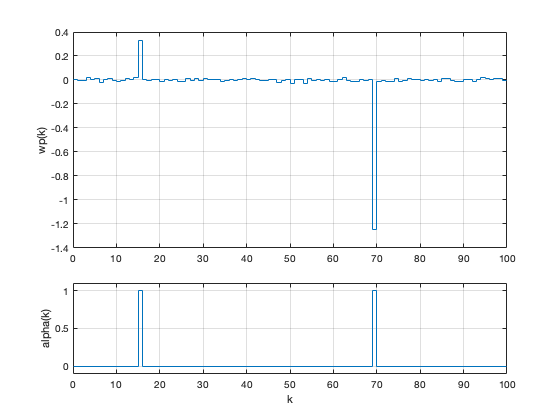

% Reset random number generator
seed = 22;
rng(seed)

% Sequence length
nT = 100;

% RODD random variable parameters
epsilon = 0.01;
sigma_w = [0.01; 1];

[Wp, alpha] = sample_random_shocks(nT+1, epsilon, sigma_w(2), sigma_w(1));

figure(1)
subplot(3,1,[1 2])

stairs(0:nT,Wp); grid on
ylabel('wp(k)')
subplot(3,1,3)
stairs(0:nT, alpha); grid on
ylim([-0.1 1.1])
xlabel('k')
ylabel('alpha(k)')

## 2. First order SISO system with one input disturbance

Consider the following linear dynamic system which consists of a process transfer function, an additive input disturbance, a measurement noise at the output, and a Kalman filter:

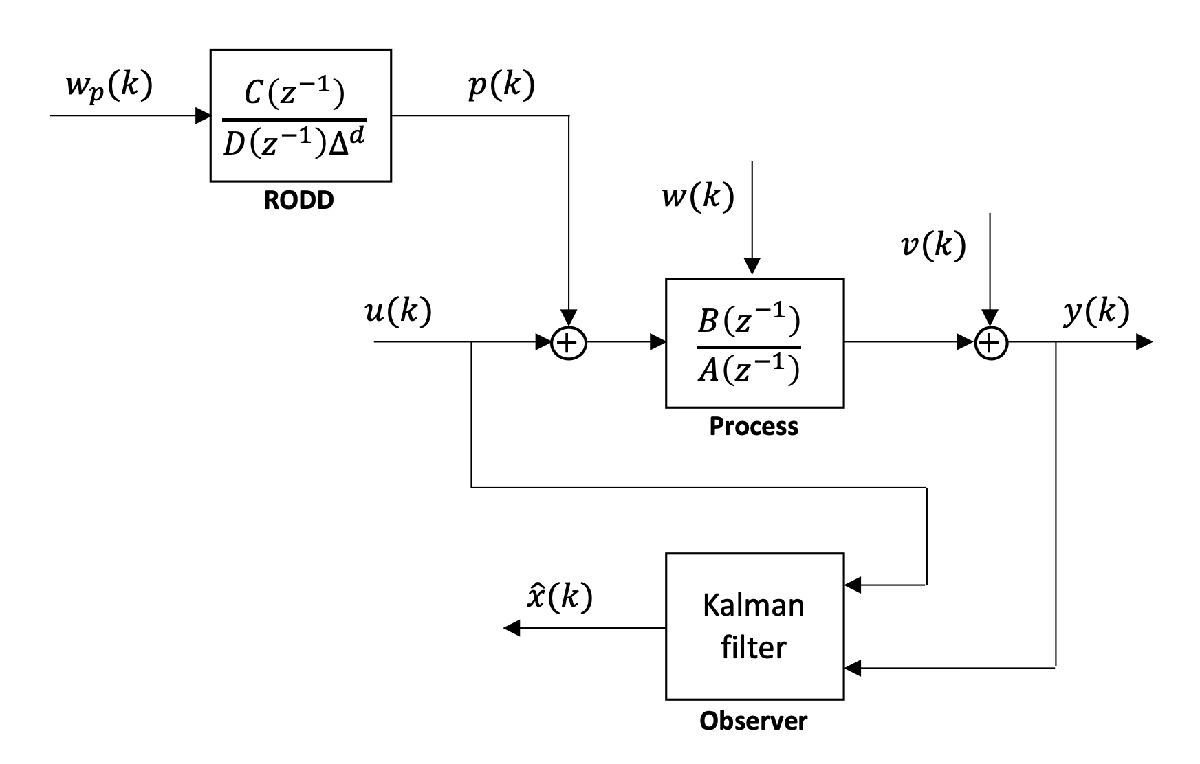

In this example, we will use a discrete system model defined in the file:

- `sys_rodin_step.m`

% Import system
sys_rodin_step
% Process transfer function
Gd

Gd =
 
    0.3
  -------
  z - 0.7
 
Sample time: 0.5 seconds
Discrete-time transfer function.



% RODD transfer function
HDd

HDd =
 
    1
  -----
  z - 1
 
Sample time: 0.5 seconds
Discrete-time transfer function.



The state-space representation of the augmented system is included in `sys_rodin_step.m`.

A, B, C, D, Ts

A =     0.7000    1.0000
         0    1.0000


B =      1     0
     0     1


C =     0.3000         0


D =      0     0


Ts = 0.5000

Gpss

Gpss =
 
  A = 
        x1   x2
   x1  0.7    1
   x2    0    1
 
  B = 
       u1  u2
   x1   1   0
   x2   0   1
 
  C = 
        x1   x2
   y1  0.3    0
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 0.5 seconds
Discrete-time state-space model.



n, nu, ny

n = 2

nu = 2

ny = 1

Simulate system

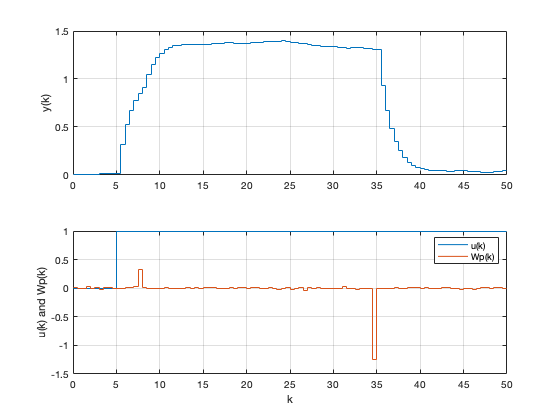

X0 = zeros(n,1);
t = Ts*(0:nT)';
U = zeros(nT+1,1);
U(t>=5) = 1;
[Y,T,X] = lsim(Gpss,[U Wp],t,X0);

figure(2)
subplot(2,1,1)
stairs(t,Y); grid on
ylabel('y(k)')
subplot(2,1,2)
stairs(t, [U Wp]); grid on
xlabel('k')
ylabel('u(k) and Wp(k)')
legend('u(k)', 'Wp(k)')

### 3. Kalman filter simulation

The function `kalman_filter` can be used to instantiate a struct variable containing the parameters to simulate a standard Kalman filter:

% Parameters
P0 = eye(2);
Q = diag([0.01 0.2]);
R = 0.1^2;
KF1 = kalman_filter(A,B,C,D,Ts,P0,Q,R,'KF1');
KF1

KF1 = struct with fields:
              A: [2×2 double]
              B: [2×2 double]
              C: [0.3000 0]
              D: [0 0]
             Ts: 0.5000
             P0: [2×2 double]
              P: [2×2 double]
              Q: [2×2 double]
              R: 0.0100
          label: 'KF1'
         status: 1
              K: [2×1 double]
    static_gain: 0
       xkp1_est: [2×1 double]
       ykp1_est: 0


The `update_KF` function is used to simulate the observer in discrete time-steps

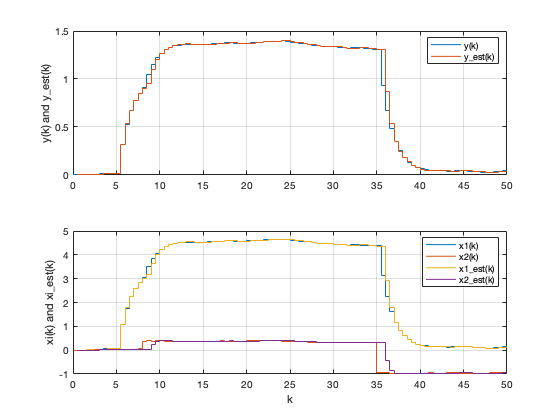

% Arrays to store simulation results
Xk_est = nan(nT+1,n);
Yk_est = nan(nT+1,ny);
obs = KF1;
for i = 1:nT
    uk = U(i,:)';
    yk = Y(i,:)';
    obs = update_KF(obs, [uk; 0], yk);
    Xk_est(i+1,:) = obs.xkp1_est';
    Yk_est(i+1,:) = obs.ykp1_est';
end

figure(3)
subplot(2,1,1)
stairs(t,[Y Yk_est]); grid on
ylabel('y(k) and y_est(k)')
legend('y(k)','y_est(k)')
subplot(2,1,2)
stairs(t, [X Xk_est]); grid on
xlabel('k')
ylabel('xi(k) and xi_est(k)')
legend('x1(k)','x2(k)','x1_est(k)','x2_est(k)')

% Calculate mean-squared error in state estimates
mse = mean((X(2:end,:) - Xk_est(2:end,:)).^2, [1 2])

mse = 0.0295

### 4. Sub-optimal multi-model observer simulation

The function `mkf_filter_RODD` can be used to instantiate a struct variable containing parameters to simulate a sub-optimal multi-model observer as described by Robertson *et al. *(1995).

Use the help function for details on this function.

help mkf_filter_RODD

  obs = mkf_filter_RODD(A,B,C,D,Ts,u_meas,P0,epsilon,sigma_wp, ...
    Q0,R,f,m,d,label,x0)
 
  Creates a struct for simulating a multi-model Kalman 
  filter for state estimation in the presence of randomly-
  occurring deterministic disturbances (RODDs) as described
  in Robertson et al. (1995).
 
  Arguments:
    A, B, C, D : discrete time system matrices.
    Ts : sample period.
    u_meas : binary vector indicating measured inputs.
    P0 : Initial value of covariance matrix of the state
        estimates.
    epsilon : probability of a shock disturbance.
    sigma_wp : standard deviation of shock disturbances.
    Q0 : initial process noise covariance matrix (n, n) with 
         variances for each state on the diagonal. The  
         values Q(i, i) for i representing the unmeasured 
         input states (where u_meas = false), will
         be modified for each filter by multiplying by the
         appropriate variances in sigma_wp.
    R : output measurement 

% Define multi-model filter
P0 = 1000*eye(n);
Q0 = diag([0.01 1]);
R = sigma_M^2;
f = 3;  % fusion horizon
m = 2;  % maximum number of shocks
d = 5;  % spacing parameter
MKF1 = mkf_filter_RODD(A,B,C,D,Ts,u_meas,P0,epsilon,sigma_wp, ...
    Q0,R,f,m,d,'MKF1');
MKF1

MKF1 = struct with fields:
                  A: {[2×2 double]  [2×2 double]}
                  B: {[2×2 double]  [2×2 double]}
                  C: {[0.3000 0]  [0.3000 0]}
                  D: {[0 0]  [0 0]}
                 Ts: 0.5000
                  Q: {[2×2 double]  [2×2 double]}
                  R: {[0.0100]  [0.0100]}
                seq: {7×1 cell}
                  T: [2×2 double]
                  d: 5
              label: 'MKF1'
                  P: {[2×2 double]  [2×2 double]  [2×2 double]  [2×2 double]  [2×2 double]  [2×2 double]  [2×2 double]}
                  i: [NaN NaN]
             i_next: [1 1]
         p_seq_g_Yk: [7×1 double]
    p_yk_g_seq_Ykm1: [7×1 double]
    p_gammak_g_Ykm1: [7×1 double]
          p_gamma_k: [7×1 double]
       p_seq_g_Ykm1: [7×1 double]
            filters: {7×1 cell}
           xkp1_est: [2×1 double]
           ykp1_est: 0
                 nj: 2
                  n: 2
                 nu: 2
                 ny: 1
             n_filt: 7
  

Inspect observer parameters

% Disturbance sequences for each filter
cell2mat(MKF1.seq)

ans =      0     0     0
     1     0     0
     0     1     0
     0     0     1
     1     1     0
     1     0     1
     0     1     1


% Sequence probabilities (unconditioned)
MKF1.p_seq

ans =     0.8601
    0.0443
    0.0443
    0.0443
    0.0023
    0.0023
    0.0023


% Total probability of all sequences modelled (ideally, should be > 0.99)
MKF1.beta

ans = 0.9999

The `update_MKF` function is used to simulate the observer

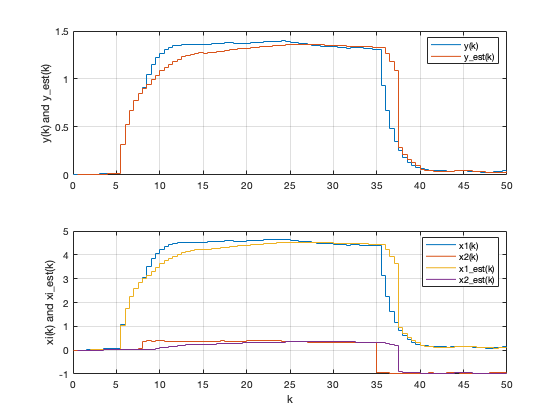

% Arrays to store simulation results
Xk_est = nan(nT+1,n);
Yk_est = nan(nT+1,ny);
obs = MKF1;
for i = 1:nT
    uk = U(i,:)';
    yk = Y(i,:)';
    obs = update_MKF(obs, [uk; 0], yk);
    Xk_est(i+1,:) = obs.xkp1_est';
    Yk_est(i+1,:) = obs.ykp1_est';
end

figure(4)
subplot(2,1,1)
stairs(t,[Y Yk_est]); grid on
ylabel('y(k) and y_est(k)')
legend('y(k)','y_est(k)')
subplot(2,1,2)
stairs(t, [X Xk_est]); grid on
xlabel('k')
ylabel('xi(k) and xi_est(k)')
legend('x1(k)','x2(k)','x1_est(k)',['x2_est(k)'])

% Calculate mean-squared error in state estimates
mse = mean((X(2:end,:) - Xk_est(2:end,:)).^2, [1 2])

mse = 0.1498

### 5. Sub-optimal adaptive forgetting through multiple models (AFMM) observer simulation

The function `mkf_filter_AFMM` can be used to instantiate a struct variable containing parameters to simulate the AFMM sub-optimal multi-model observer as described by Eriksson and Isaksson (1996).

Use the help function for details on this function.

help mkf_filter_AFMM

  obs = mkf_filter_AFMM(A,B,C,D,Ts,u_meas,P0,epsilon,sigma_wp, ...
      Q0,R,n_filt,f,n_min,label,x0)
 
  Creates a struct for simulating the multi-model Kalman
  filter using the adaptive forgetting through multiple
  models (AFMM) method for state estimation in the presence 
  of infrequently-occurring deterministic disturbances, 
  as described in Eriksson and Isaksson (1996).
 
  Arguments:
    A, B, C, D : discrete time system matrices.
    Ts : sample period.
    u_meas : binary vector indicating measured inputs.
    P0 : Initial value of covariance matrix of the state
        estimates.
    epsilon : probability of a shock disturbance.
    sigma_wp : standard deviation of shock disturbances.
    Q0 : initial process noise covariance matrix (n, n) with 
        variances for each state on the diagonal. The  
        values Q(i, i) for i representing the unmeasured 
        input states (where u_meas = false), will
        be modified for each filter by multiplyi

% Define multi-model filter
P0 = 1000*eye(n);
Q0 = diag([0.01 1]);
R = sigma_M^2;
f = 10;  % sequence history length
n_filt = 4;  % number of filters
n_min = 2;  % minimum life of cloned filters
AFMM1 = mkf_filter_AFMM(A,B,C,D,Ts,u_meas,P0,epsilon,sigma_wp, ...
    Q0,R,n_filt,f,n_min,'AFMM1');

Inspect selected observer parameters

% Initial filter probabilities
AFMM1.p_seq_g_Yk

ans =     0.2500
    0.2500
    0.2500
    0.2500


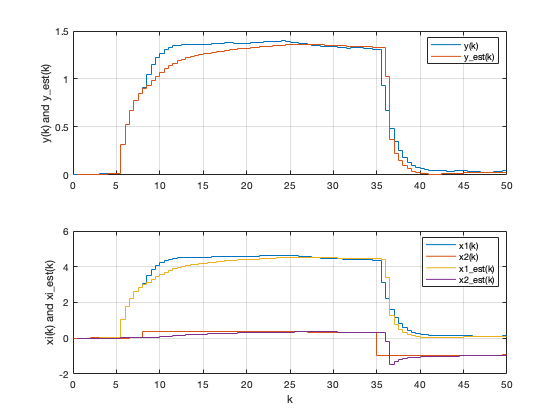

% Arrays to store simulation results
Xk_est = nan(nT+1,n);
Yk_est = nan(nT+1,ny);
obs = AFMM1;
for i = 1:nT
    uk = U(i,:)';
    yk = Y(i,:)';
    obs = update_AFMM(obs, [uk; 0], yk);
    Xk_est(i+1,:) = obs.xkp1_est';
    Yk_est(i+1,:) = obs.ykp1_est';
end

figure(4)
subplot(2,1,1)
stairs(t,[Y Yk_est]); grid on
ylabel('y(k) and y_est(k)')
legend('y(k)','y_est(k)')
subplot(2,1,2)
stairs(t, [X Xk_est]); grid on
xlabel('k')
ylabel('xi(k) and xi_est(k)')
legend('x1(k)','x2(k)','x1_est(k)',['x2_est(k)'])

% Calculate mean-squared error in state estimates
mse = mean((X(2:end,:) - Xk_est(2:end,:)).^2, [1 2])

mse = 0.0702

## References

- Robertson, D. G., Kesavan, P., & Lee, J. H. (1995). Detection and estimation of randomly occurring deterministic disturbances. *Proceedings of 1995 American Control Conference - ACC’95*, *6*, 4453–4457. [https://doi.org/10.1109/ACC.1995.532779.](https://doi.org/10.1109/ACC.1995.532779.)

- Eriksson, P.-G., & Isaksson, A. J. (1996). Classification of Infrequent Disturbances. *IFAC Proceedings Volumes*, *29*(1), 6614–6619. [https://doi.org/10.1016/S1474-6670(17)58744-3](https://doi.org/10.1016/S1474-6670(17)58744-3).